The goal of this assignment is to recreate the forest and the trees simulation.

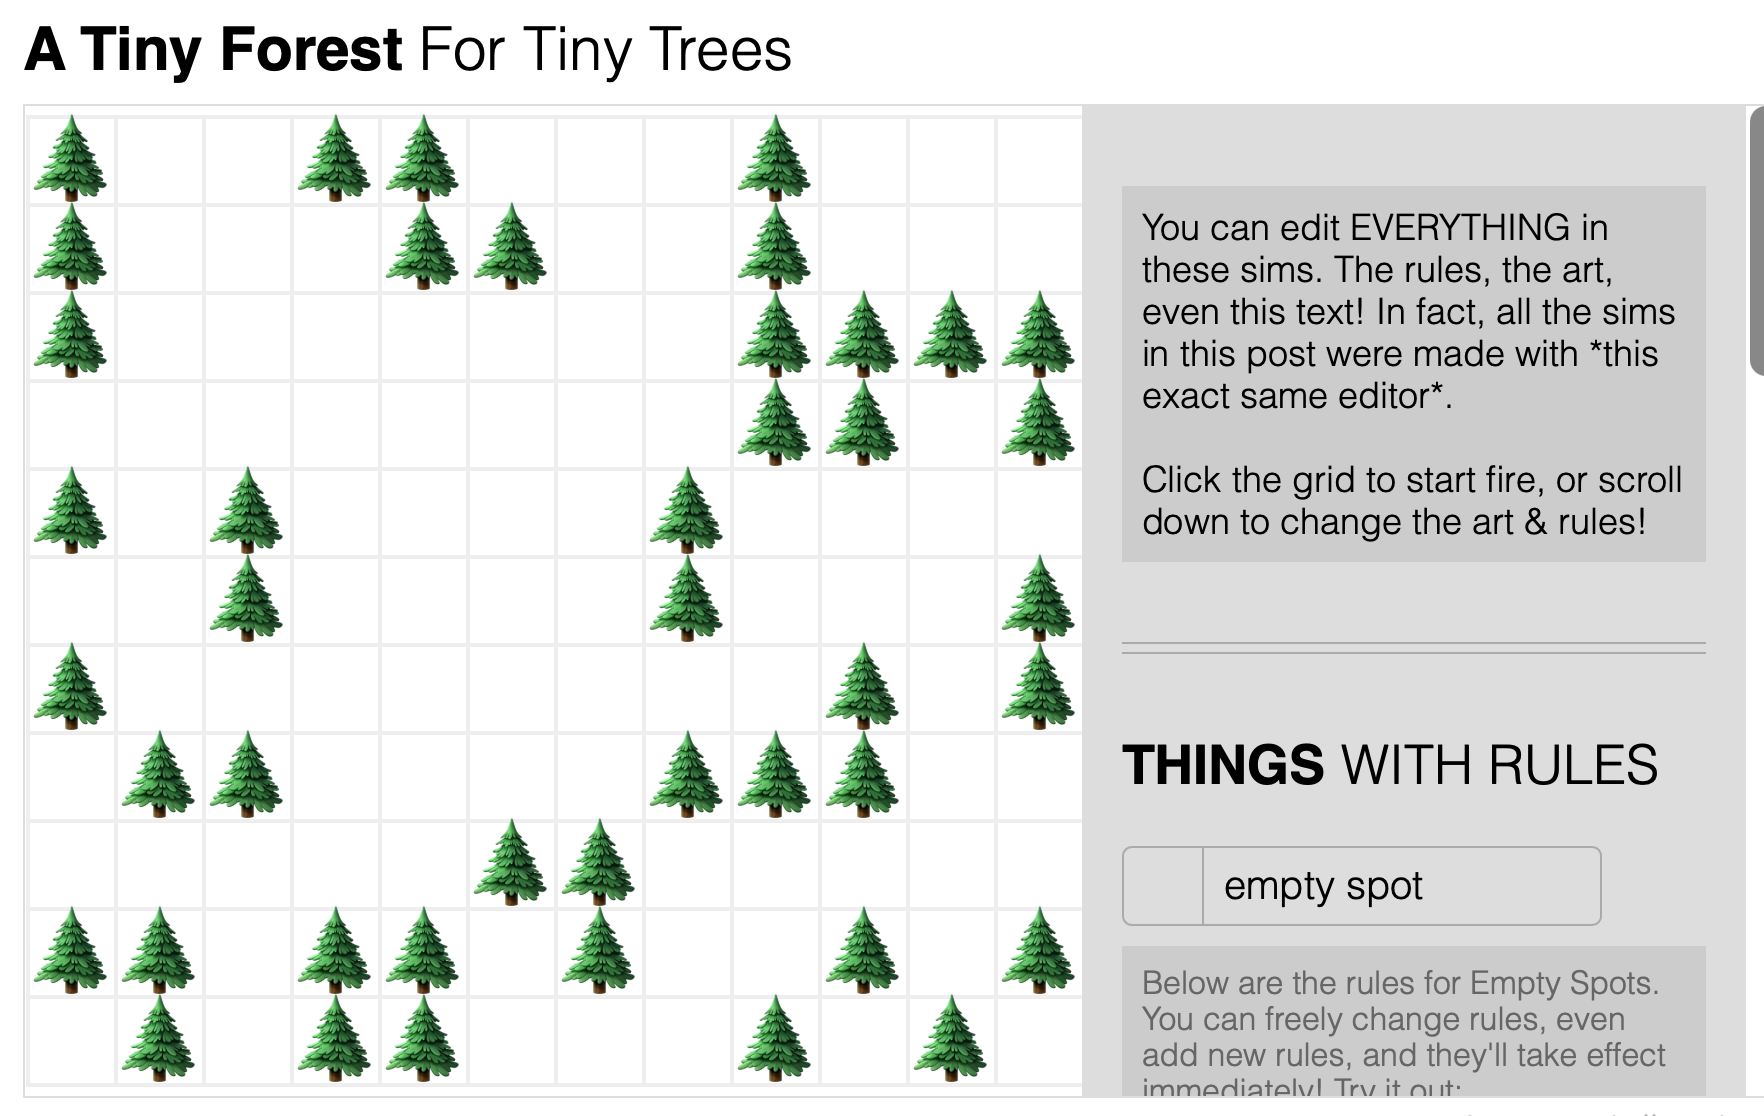

Similar to past simulations, you will be looking at a variable at a moment in time, applying some rules or equations to that variable, and then determining the variable at the next moment in time.

But there are several differences from past simulations:

- The forest data is in two dimensions 

- Each cell of the forest data has three different possible states: empty, tree, and fire

**Task 1:**

Start by initializing your variables.

- ***forestSizeX, forestSizeY***: these will specify the overall size of your forest. Start with 20,20 for these values

- ***forest()***: this will be the 2D matrix that contains the information about your forest. You should initialize this with the zeros function, using the x and y sizes above. 

- ***forestNext()***: this will be the forest at the next point in time. Initialize this with the zeros function just like the forest matrix above.

- Each location in the forest can be one of three different things. Setup these variables that you will assign to these cells: ***empty=0; tree=1; fire=2;***

- ***treeGrowthRate***: this is the chance that a blank square turns into a tree. As a starting point set this to 1% or 0.01

- ***treeDeathRate***: this is the chance that a tree will natually die from a means other than fire (this was not part of the original online simulaiton). As a starting point, set this to 0.1% or 0.001

- ***fireSparkRate***: this is the chance that a tree will catch on fire from a lightning strike or human accident. As a starting point, set this to 0.5% or 0.005.

- ***simulationTimeSteps***: this is how many time steps you will have in your simulation. A good starting point is 1000.

clc; clear; close all;

%initialize variables as described above

forestSizeX = 20;
forestSizeY = 20;
forest = zeros (20);
forestNext = zeros (20);
treeGrowthRate = 0.01;
treeDeathRate = 0.001;
fireSparkRate = 0.005;
simulationTimeSteps = 1000;

empty = 0;
tree = 1;
fire = 2;

To make sure that everything looks ok so far, use the ***imagesc(forest)*** command. Set color limits to the range of possible values in your forest, using ***clim [empty fire]***, which is the range of possible data values in your forest. Uste the ***colorbar*** statement to display a color scale next to the plot. The resulting figure should be a blank blue background grid with size forestSizeX, forestSizeY.

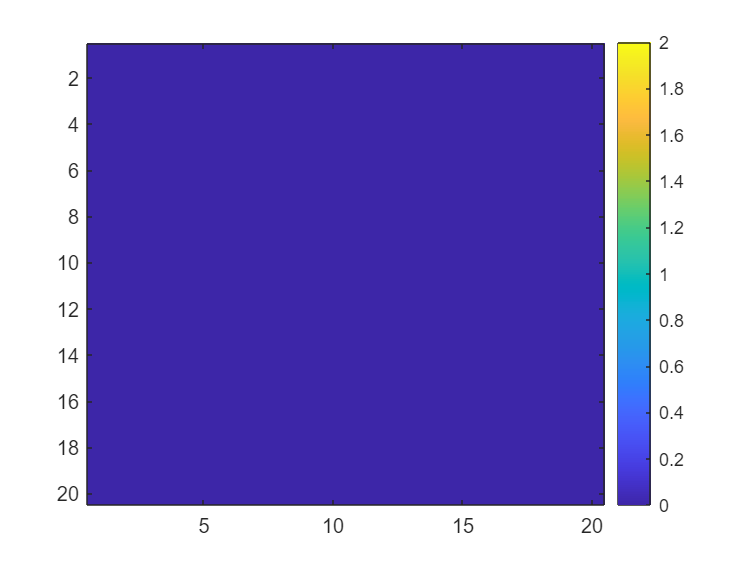

%put your plotting statements below, as described above

imagesc(forest, [empty fire])
colorbar

**Task 2:**

Let's expand the simulation so that trees can grow, but don't try adding the fire or natural death yet (let's take this one step at a time). The idea here is you'll go through each element of the forest and if it's empty, see if a tree should grow or die. If there's already a tree, see if it should die of natural causes. During this process you'll look at the current "forest" matrix, and generate a new "forestNext" matrix.

**We have already done the following steps for you!**

a. Setup three nested for loops as described in the ppt slides:

- loop the t variable from 1 to simulationTimeSteps

- loop the i variable from 2 through forestSizeX-1

- loop the j variable from 2 through forestSizeY-1

Notice that you should not loop from 1 to forestSizeX or forestSizeY. Why? The reason is that later on, you will be checking every tree to see if any neighbors are on fire. This is a little trickier if you are at the edge of the forest. So, instead, you can make this easier by setting up the loops to start and end one cell away from the edges.

b. Inside the inner for loop, check the current cell of the forest and check if it's empty, contains a tree, or contains a tree that's on fire. This series of ***if*** statements appear in the code below.

**Now, you need to modify the code below for the following:**

When the current cell is empty, apply the rules of this simulation to see if a tree should grow using the following code: 

***   if (rand <= treeGrowthRate)***

***           forestNext(i,j)=tree;***

***   end***

After the i,j ***for*** loops, set ***forest=forestNext ***and display the new forest. For the imagesc plotting command here, you also need to include "drawnow" so that Matlab redraws the image every time through the loop.

Before running this section, be sure to check each variable assignment statement and make sure there is a ";" at the end, so that the output doesn't get cluttered.

You should see new trees appear in the forest as time goes on. Depending on the values of treeGrowthRate and simulationTimeSteps, the entire grid may fill up with trees.

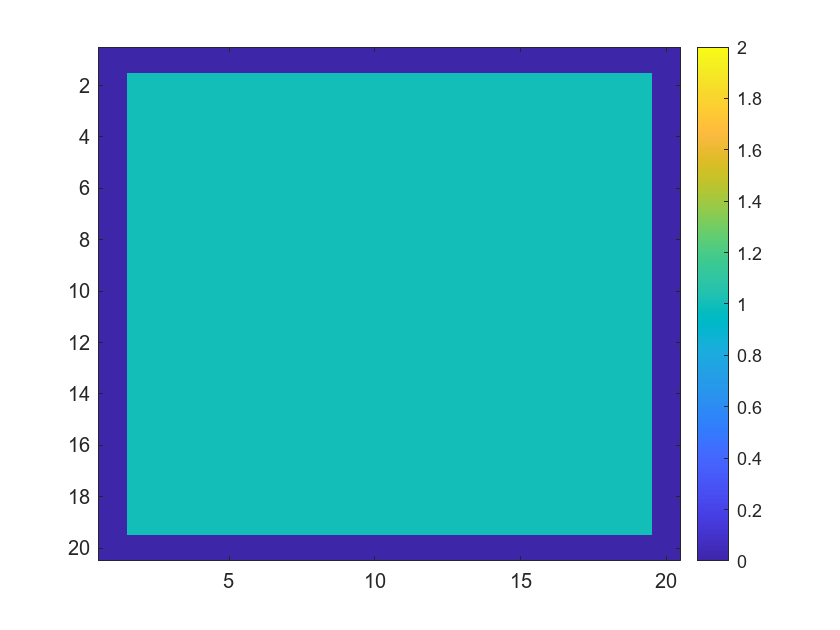

clc; clear; close all;

%copy your initialization code from task 1
forestSizeX = 20;
forestSizeY = 20;
forest = zeros (20);
forestNext = zeros (20);
treeGrowthRate = 0.5;
treeDeathRate = 0.001;
fireSparkRate = 0.005;
simulationTimeSteps = 1000;

empty = 0;
tree = 1;
fire = 2;
% go through each instant in time
for t=1:simulationTimeSteps

    % Go through every location in your forest
    for i=2:forestSizeX-1
        for j=2:forestSizeY-1
            % check forest(i,j), and determine if it’s empty, tree, or fire
            % based on this decide, if forestNext(i,j) should be set to empty, tree, or fire
            if forest(i,j)==empty
                % current cell is empty
                % add code here to execute if current cell is empty
                if rand <= treeGrowthRate
                    forestNext(i, j) = tree;
                end


            elseif forest(i,j)==tree
                % current cell is a tree
            elseif forest(i,j)==fire
                % current cell is a fire
            else
                forestNext(i,j)=forest(i,j)
            end

        end % for j loop
    end % for i loop

    % now you have established what the forest should look like at the next
    % point in time; it is stored in "forestNext"; copy this to the "forest" matrix

    forest = forestNext;

    % display the updated forest
    % copy the code from the end of task 1 that displays your forest
imagesc(forest, [empty fire]);
colorbar;

    %this next line forces matlab to update the figure each time through
    %the "for" loop
    drawnow;

end

**Task 3:**

Once you get task 2 working above, it's time to add the fire to the simulation (fireSparkRate) and also for trees to die naturally (treeDeathRate). For now, the fire will not spread; you will implement that later.

Copy your working code from task 2 to the space below. Within the inner ***for*** loop, you already have code that checks the current value of forest(i,j) to see if it's empty, a tree, or on fire. Now add some code to act according to the rules of the forest simulation:

- if the current cell is empty: use the rand function and ***treeGrowthRate ***to determine if it should grow into a tree: ***forestNext(i,j)=tree***.  *(You have already done this)*

- if the current cell is a tree: use the rand function and ***fireSparkRate ***to determine if it should be set on fire: ***forestNext(i,j)=fire***. Also, use the rand function and ***treeDeathRate*** to determine if it should die naturally: ***forestNext(i.j)=empty***.

- if the current cell is on fire, then set it should automatically die and become empty: ***forestNext(i,j)=empty***.

Once again, before running this section of the program, be sure to check each variable assignment statment and make sure there is a ";" at the end, so that the output doesn't get cluttered.

When you run this, you should see trees (teal) growing and occassionally dying of natural causes or turning into fire (yellow) just before dying.

%copy your working code from task 2 here and make changes as 
% described above

clc; clear; close all;

%copy your initialization code from task 1
forestSizeX = 20;
forestSizeY = 20;
forest = zeros (20);
forestNext = zeros (20);
treeGrowthRate = 0.5;
treeDeathRate = 0.001;
fireSparkRate = 0.005;
simulationTimeSteps = 1000;

empty = 0;
tree = 1;
fire = 2;
% go through each instant in time
for t=1:simulationTimeSteps

    % Go through every location in your forest
    for i=2:forestSizeX-1
        for j=2:forestSizeY-1
            % check forest(i,j), and determine if it’s empty, tree, or fire
            % based on this decide, if forestNext(i,j) should be set to empty, tree, or fire
            if forest(i,j)==empty
                % current cell is empty
                % add code here to execute if current cell is empty
                if rand <= treeGrowthRate
                    forestNext(i, j) = tree;
                end


            elseif forest(i,j)==tree
                % current cell is a tree
                if rand <= fireSparkRate
                    forestNext(i, j) = fire;
                elseif rand <= treeDeathRate
                    forestNext(i, j) = empty;
                end


            
            elseif forest(i,j)==fire
                % current cell is a fire
                forestNext(i, j) = empty;
            else
                forestNext(i,j)=forest(i,j);
            end

        end % for j loop
    end % for i loop

    % now you have established what the forest should look like at the next
    % point in time; it is stored in "forestNext"; copy this to the "forest" matrix

    forest = forestNext;

    % display the updated forest
    % copy the code from the end of task 1 that displays your forest
imagesc(forest, [empty fire]);
colorbar;

    %this next line forces matlab to update the figure each time through
    %the "for" loop
    drawnow;

end


**Task 4**

Once you get task 3 working, you are ready add code so that the fire can spread. If the current cell is a tree and any of its neighbors are on fire, then the current cell should catch on fire. This is how the fire spreads. Look at the ppt slides to see how to do this.

%copy your entire working code from task 3 here
% and make changes as described above so that the fire can spread

clc; clear; close all;

%copy your initialization code from task 1
forestSizeX = 20;
forestSizeY = 20;
forest = zeros (20);
forestNext = zeros (20);
treeGrowthRate = 0.005;
treeDeathRate = 0.001;
fireSparkRate = 0.005;
simulationTimeSteps = 1000;

empty = 0;
tree = 1;
fire = 2;
% go through each instant in time
for t=1:simulationTimeSteps

    % Go through every location in your forest
    for i=2:forestSizeX-1
        for j=2:forestSizeY-1
            % check forest(i,j), and determine if it’s empty, tree, or fire
            % based on this decide, if forestNext(i,j) should be set to empty, tree, or fire
            if forest(i,j)==empty
                % current cell is empty
                % add code here to execute if current cell is empty
                if rand <= treeGrowthRate
                    forestNext(i, j) = tree;
                end


            elseif forest(i,j)==tree
                % current cell is a tree
                neighbors=forest(i-1:i+1,j-1:j+1);
                if any(neighbors(:) == fire);
                    forestNext(i, j) = fire;
                elseif rand <= treeDeathRate
                    forestNext(i, j) = empty;
                end


            
            elseif forest(i,j)==fire
                % current cell is a fire
                forestNext(i, j) = empty;
            else
                forestNext(i,j)=forest(i,j);
            end

        end % for j loop
    end % for i loop

    % now you have established what the forest should look like at the next
    % point in time; it is stored in "forestNext"; copy this to the "forest" matrix

    forest = forestNext;

    % display the updated forest
    % copy the code from the end of task 1 that displays your forest
imagesc(forest, [empty fire]);
colorbar;

    %this next line forces matlab to update the figure each time through
    %the "for" loop
    drawnow;

end

**Task 5**

Once you reach this point, you have a simulation that is comparable to the first web-based simulation that you did at the start of the semester. 

Now, it's time to make modifications to answer your design question.

- Create a new type of entity that can be in your forest: ***house=3; ***Adjust the clim command to reflect that you now have a new feature to display: ***clim([empty house])***

- The house is protected by fire-resistant wrapping, which has a small chance of burning. Let's assume this is 0.1%. Initialize the variable ***fireResistance=0.001;***

- After you create an empty forest with the zeros function, choose any three fixed locations in the forest and turn those into a house.

- Add the following rule for your house: if it is adjacent to fire, the chance that it will burn is determined by the value of ***fireResistance.***

- Adjust the value of ***fireResistance ***to see if any of the houses have burned down by the time that the simulation is finished. 

If you run your program as a ".m" script instead of an ".mlx" live script, it will execute faster, so for this last task, create a new file, "forestSimulationTask5_<yourname>.m" with your solution. Copy your working task 4 code as a starting point and modify it to add your new features.